# HW4

## Preprocessing

clear global

% Reading in the Excel file as a table then converting it into a matrix
mytable = readtable('Validation.xlsx');
x = mytable{2:3,13:end};
x = transpose(x);

% 1st column: cumulative number of detected infections
V = x(:,1)

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% 2nd column: Covid-19 related deaths reported in that specific county/city
Y = x(:,2)

Y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Exercise One Preprocessing

%%
Nmax = 705749; % Max population; from Population column
Tmax = 40;    % Number of days we will attempt to model
Vmin = 5;      % See below
tau0 = 7;      % Time between infection and full symptom onset
h = 0.01;      % Step size

% Sets used in omega set generation 
alphaSet = 0.05:0.01:0.2;
R0Set = 1.5:0.1:1.9;
NfracSet = 0.02:0.01:0.1;
deltaSet = 0.05:0.01:0.4;

% Norm used in error calculation
pSet = [1 2 inf];
pLen = length(pSet);

% Get the first day where at least Vmin were detected as infected
for i = 1:size(x, 1)
    if x(i,1) >= 5
        break
    end
end
t0 = i

t0 = 55


% Preprocess rate of infections
I = zeros(Tmax+1,1); % note that I(t) represent the value of I at t+1
for t=0:Tmax
    I(t+1) = V(t+t0+tau0) - V(t+t0-tau0);
end
I;

I0 = I(1)

I0 = 120

Tmax_new = 119

Tmax_new = 119

I_new = zeros(Tmax_new+1,1); % note that I(t) represent the value of I at t+1
for t=0:Tmax_new
    I_new(t+1) = V(t+t0+tau0) - V(t+t0-tau0);
end
I_new;

I0 = I(1)

I0 = 120

## Exercise One Part 1

% Get parameters
% Function defined in generateParams1.m
[alphaLen, betaLen, NLen, omega1] = ...
    generateParams1(alphaSet, R0Set, NfracSet, Nmax);

% Testing Euler scheme function defined in SEIR_euler.m
params = num2cell(squeeze(omega1(1,1,1,:)));
[alpha, beta, N] = params{:}

alpha = 0.0500

beta = 0.0750

N = 1.4115e+04

[Ssim, Isim, Rsim] = SIR_euler(I0,Tmax,alpha,beta,N)

Ssim = 	1.0e+04 *

    1.4115
    1.4106
    1.4097
    1.4087
    1.4077
    1.4067
    1.4057
    1.4046
    1.4036
    1.4025


Isim =   120.0000
  123.0345
  126.1395
  129.3165
  132.5666
  135.8912
  139.2918
  142.7695
  146.3258
  149.9619


Rsim =          0
    6.0748
   12.3031
   18.6884
   25.2344
   31.9447
   38.8231
   45.8734
   53.0996
   60.5055


[gamma, minVal] = minimizeGamma(t0, Tmax, Y, Rsim, 1)

gamma = 0.2714

minVal = 670.4691

% gammas(alphaInd, betaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, N)
% J(...) contains the minimized function value
gammas = zeros(alphaLen, betaLen, NLen, pLen);
J = zeros(alphaLen, betaLen, NLen, pLen);

fprintf("alphas iterated over:")

alphas iterated over:

for alphaInd = 1:alphaLen
    fprintf("%.2f, ", alphaSet(alphaInd))
    for betaInd = 1:betaLen
        for NInd = 1:NLen
            % Get parameters from set, use Euler scheme
            params = num2cell(squeeze(omega1(alphaInd, betaInd, NInd, :)));
            [alpha, beta, N] = params{:};
            [Ssim, Isim, Rsim] = SIR_euler(I0, Tmax, alpha, beta, N);
            
            % For each p, find gamma minimizing p-norm & store
            for pInd = 1:pLen
                p = pSet(pInd);
                % Function defined in minimizeGamma.m
                [gamma, ~] = minimizeGamma(t0, Tmax, Y, Rsim, p);
                gammas(alphaInd, betaInd, NInd, pInd) = gamma;
                %Y(t0:t0+Tmax)
                %size(I)
                %I(t0:t0+Tmax)
                J(alphaInd, betaInd, NInd, pInd) = objectiveFunction(Y(t0:t0+Tmax), Rsim, I, Isim, gamma, 1, p);
            end
        end
    end
end

0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

paramMinp = cell(pLen,4); % Store {alpha, beta, gamma, N}

% For each p value...
for pInd = 1:pLen
    p = pSet(pInd);
    Jp = J(:,:,:,pInd);
    gammasp = gammas(:,:,:,pInd);

    % Get index of minimum error 
    [M, Ind] = min(Jp, [], "all");
    [alphaMinInd, betaMinInd, NMinInd] = ind2sub(size(Jp),Ind);

    % Find parameters at that index
    gammaMin = gammasp(Ind);
    omegaTemp = reshape(omega1, [], 3);
    paramMin = num2cell(omegaTemp(Ind,:));
    [alphaMin, betaMin, NMin] = paramMin{:};
    
    % Print result
    fprintf("For p = %d, the parameters which reduce the error are\n" + ...
        "alpha = %.3f, beta = %.3f, gamma = %.3f, N = %g\n" + ...
        "(R0 = %.3f, Nfrac = %.3f)\n" + ...
        "with an error of %f\n\n", ...
        p,alphaMin, betaMin, gammaMin, NMin, betaMin / alphaMin, NMin / Nmax, M);
    % Store minimum parameter values for Exercise 1 Part 3
    paramMinp(pInd,:) = {alphaMin, betaMin, gammaMin, NMin};
end

For p = 1, the parameters which reduce the error are
alpha = 0.160, beta = 0.304, gamma = 0.016, N = 14115
(R0 = 1.900, Nfrac = 0.020)
with an error of 6539.131166

For p = 2, the parameters which reduce the error are
alpha = 0.160, beta = 0.304, gamma = 0.017, N = 14115
(R0 = 1.900, Nfrac = 0.020)
with an error of 1328.434533

For p = Inf, the parameters which reduce the error are
alpha = 0.190, beta = 0.323, gamma = 0.016, N = 21172.5
(R0 = 1.700, Nfrac = 0.030)
with an error of 418.060868



## Exercise One Part 2

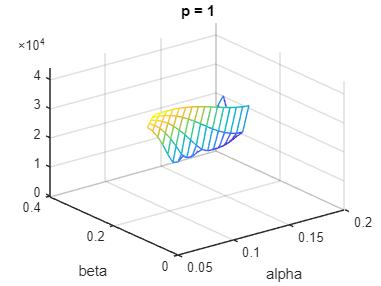

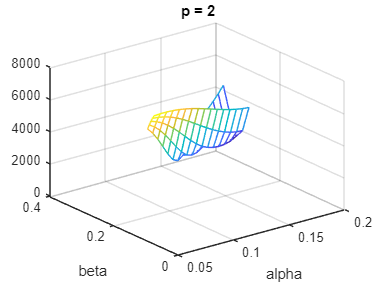

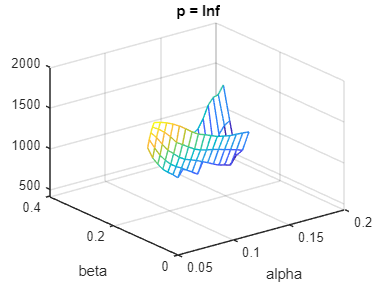

% (α, β) → J = J(α, β, N-hat, γ-hat)
for pInd = 1:pLen
    params = omega1(:, :, NMinInd, :);
    alphas = reshape(params(:,:,:,1), alphaLen, []);
    betas = reshape(params(:,:,:,2), [], betaLen);
    Jparams = J(:, :, NMinInd, pInd); 

    figure
    mesh(alphas, betas, Jparams);
    title(['p = ', num2str(pSet(pInd))])
    xlabel("alpha"); ylabel("beta")
end

## Exercise One Part 3

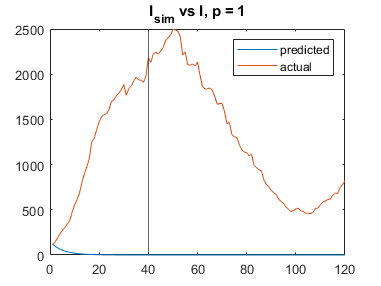

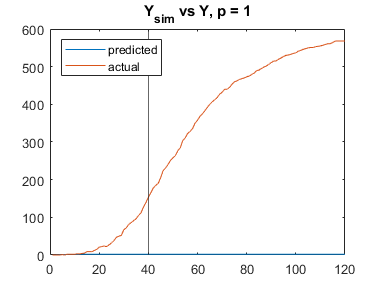

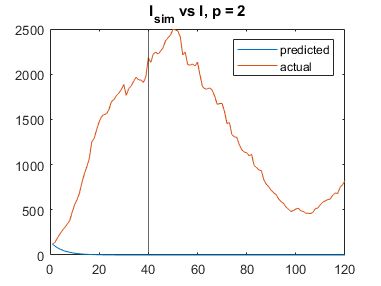

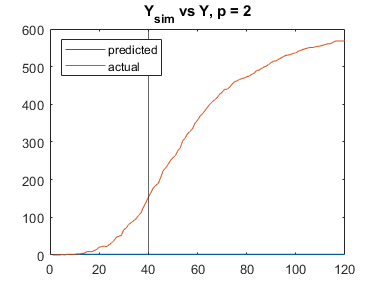

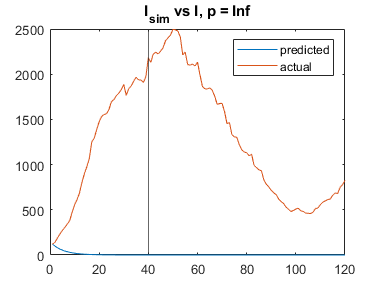

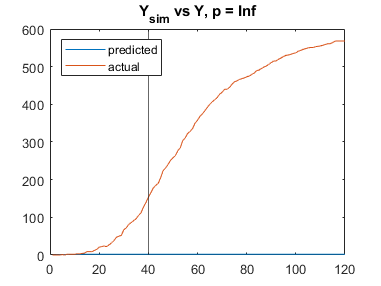

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp(pInd,:);
    [alphaMin, betaMin, gammaMin, NMin] = paramMin{:};
    % Recalculated because it's not stored previously
    [Ssim, Isim, Rsim] = SIR_euler(I0, 119, alphaMin, betaMin, NMin);

    % (i) Compare Isim and I
    figure
    plot(Isim)
    hold on
    plot(I_new)
    hold off
    xline(40)
    legend(["predicted", "actual"])
    legend('Location','northeast')
    title(['I_{sim} vs I, p = ', num2str(p)])

    % (ii) Compare Y and Ysim = gamma * Rsim
    figure
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+119))
    hold off
    xline(40)
    legend(["predicted", "actual"])
     legend('Location','northwest')
    title(['Y_{sim} vs Y, p = ', num2str(p)])
end

## Exercise One Part 4

Because for various *p* values, we got minima for alpha in {0.11}, for beta in {0.18, 0.19}, and for Nfrac in {0.02}, we would want to search in a range around those values to get more refined parameter estimates. 

Surprisingly, all values of p returned Nfrac as 0.02 and alpha as 0.11, so perhaps this truly is a good value for N/alpha, or perhaps we need to search a smaller intervals around those values.

One possible set would be:

alpha in [0.10, 0.12]

R0 in [0.17, 0.20]

Nfrac in [0.01, 0.03]. 

We also would consider much smaller increments for the parameters instead of 0.01 / 0.1. 

## Exercise 2

%%
%%
Nmax = 705749; % Max population; from Population column
Tmax = 40;    % Number of days we will attempt to model
Vmin = 5;      % See below
tau0 = 7;      % Time between infection and full symptom onset
h = 0.01;      % Step size

% Sets used in omega set generation 
alphaSet = 0.05:0.01:0.2;
R0Set = 1.5:0.1:1.9;
NfracSet = 0.02:0.01:0.1;
deltaSet = 0.05:0.01:0.4;

% Norm used in error calculation
pSet = [1 2 inf];
pLen = length(pSet);

% Get parameters
% Function defined in generateParams2.m
[alphaLen, betaLen, deltaLen, NLen, omega2] = ...
    generateParams2(alphaSet, deltaSet, R0Set, NfracSet, Nmax);

% Testing
% Euler scheme function defined in SEIR_euler.m
params = num2cell(squeeze(omega2(1,1,1,1,:)));
[alpha, beta, delta, N] = params{:}

alpha = 0.0500

beta = 0.0750

delta = 0.0500

N = 1.4115e+04

[Ssim, Esim, Isim, Rsim] = SEIR_euler(I0,Tmax,alpha,beta,delta,N)

Ssim = 	1.0e+04 *

    1.4115
    1.4106
    1.4097
    1.4088
    1.4079
    1.4070
    1.4061
    1.4052
    1.4042
    1.4033


Esim =   120.0000
  122.9259
  125.7138
  128.3797
  130.9383
  133.4023
  135.7834
  138.0918
  140.3368
  142.5268


Isim =   120.0000
  120.0718
  120.2795
  120.6100
  121.0517
  121.5944
  122.2287
  122.9464
  123.7401
  124.6033


Rsim =          0
    6.0012
   12.0094
   18.0310
   24.0720
   30.1376
   36.2327
   42.3616
   48.5282
   54.7363


[gamma, minVal] = minimizeGamma(t0, Tmax, Y, Rsim, 1)

gamma = 0.3503

minVal = 794.3215

### Exercise 2 Part 1

% gammas(alphaInd, betaInd, deltaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, delta, N)
% J(...) contains the minimized function value
gammas = zeros(alphaLen, betaLen, deltaLen, NLen, pLen);
J = zeros(alphaLen, betaLen, deltaLen, NLen, pLen);

% WARNING: Takes a while to calculate
fprintf("alphas iterated over:")

alphas iterated over:

for alphaInd = 1:alphaLen
    fprintf("%.2f, ", alphaSet(alphaInd))
    for betaInd = 1:betaLen
        for deltaInd = 1:deltaLen
            for NInd = 1:NLen
                % Get parameters from set, use Euler scheme
                params = num2cell(squeeze(omega2(alphaInd, betaInd, deltaInd, NInd, :)));
                [alpha, beta, delta, N] = params{:};
                [Ssim, Esim, Isim, Rsim] = SEIR_euler(I0, Tmax, alpha, beta, delta, N);
                
                % For each p, find gamma minimizing p-norm & store
                for pInd = 1:pLen
                    p = pSet(pInd);
                    % Function defined in minimizeGamma.m
                    [gamma, minVal] = minimizeGamma(t0, Tmax, Y, Rsim, p);
                    gammas(alphaInd, betaInd, deltaInd, NInd, pInd) = gamma;
                    J(alphaInd, betaInd, deltaInd, NInd, pInd) = objectiveFunction(Y(t0:t0+Tmax), Rsim, I, Isim, gamma, 1, p);
                end
            end
        end
    end
end

0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

% Save results (so if we need to restart we don't lose the calculations)
% Commented so that we don't overwrite the results later
writematrix(J,"hw4_ex_testingDC_errors_all_p.txt")
writematrix(gammas,"hw4_ex_testingDC_gammas_all_p.txt")

paramMinp = cell(pLen,5); % Store {alpha, beta, gamma, delta, N}

% For each p value...
for pInd = 1:pLen
    p = pSet(pInd);
    Jp = J(:,:,:,:,pInd);
    gammasp = gammas(:,:,:,:,pInd);

    % Get index of minimum error 
    [M, Ind] = min(Jp, [], "all");
    [alphaMinInd, betaMinInd, deltaMinInd, NMinInd] = ind2sub(size(Jp),Ind);

    % Find parameters at that index
    gammaMin = gammasp(Ind);
    omegaTemp = reshape(omega2, [], 4);
    paramMin = num2cell(omegaTemp(Ind,:));
    [alphaMin, betaMin, deltaMin, NMin] = paramMin{:};
    
    % Print result
    fprintf("For p = %d, the parameters which reduce the error are\n" + ...
        "alpha = %.3f, beta = %.3f, gamma = %.3f, delta = %.3f, N = %g\n" + ...
        "(R0 = %.3f, Nfrac = %.3f)\n" + ...
        "with an error of %f\n\n", ...
        p,alphaMin, betaMin, gammaMin, deltaMin, NMin, betaMin / alphaMin, NMin / Nmax, M);
    paramMinp(pInd,:) = {alphaMin, betaMin, gammaMin, deltaMin, NMin};
end

For p = 1, the parameters which reduce the error are
alpha = 0.200, beta = 0.380, gamma = 0.017, delta = 0.400, N = 21172.5
(R0 = 1.900, Nfrac = 0.030)
with an error of 11251.740539

For p = 2, the parameters which reduce the error are
alpha = 0.200, beta = 0.380, gamma = 0.018, delta = 0.400, N = 21172.5
(R0 = 1.900, Nfrac = 0.030)
with an error of 2257.860339

For p = Inf, the parameters which reduce the error are
alpha = 0.200, beta = 0.380, gamma = 0.017, delta = 0.400, N = 28230
(R0 = 1.900, Nfrac = 0.040)
with an error of 639.071724



### Exercise 2 Part 2

% (α, β) → J = J(α, β, δ-hat, N-hat, γ-hat)
for pInd = 1:pLen
    params = omega2(:, :, deltaMinInd, NMinInd, :);
    alphas = reshape(params(:,:,:,:,1), alphaLen, []);
    betas = reshape(params(:,:,:,:,2), [], betaLen);
    Jparams = J(:, :, deltaMinInd, NMinInd, pInd); 

    figure
    mesh(alphas, betas, Jparams);
    title(['p = ', num2str(pSet(pInd))])
    xlabel("alpha"); ylabel("beta")
end

% (α, δ) → J = J(α, β-hat, δ, N-hat, γ-hat)
for pInd = 1:pLen
    params = omega2(:, betaMinInd, :, NMinInd, :);
    alphas = reshape(params(:,:,:,:,1), alphaLen, []);
    deltas = reshape(params(:,:,:,:,3), [], deltaLen);
    Jparams = reshape(J(:, betaMinInd, :, NMinInd, pInd), ...
        alphaLen, deltaLen);

    figure
    mesh(alphas, deltas, Jparams);
    title(['p = ', num2str(pSet(pInd))])
    xlabel("alpha"); ylabel("delta")
end

% (β, δ) → J = J(α-hat, β, δ, N-hat, γ-hat)
for pInd = 1:pLen
    params = omega2(alphaMinInd, :, :, NMinInd, :);
    betas = reshape(params(:,:,:,:,2), betaLen, []);
    deltas = reshape(params(:,:,:,:,3), [], deltaLen);
    Jparams = reshape(J(alphaMinInd, :, :, NMinInd, pInd), ...
        betaLen, deltaLen);
    
    figure
    mesh(betas, deltas, Jparams);
    title(['p = ', num2str(pSet(pInd))])
    
    xlabel("beta"); ylabel("delta")
end

### Exercise 2 Part 3

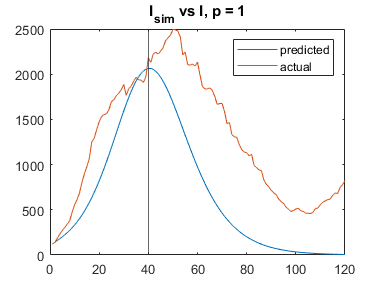

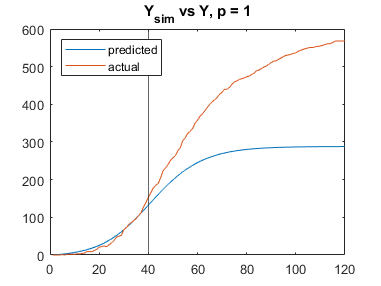

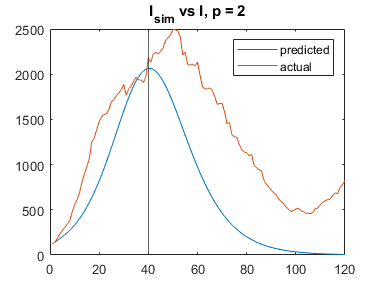

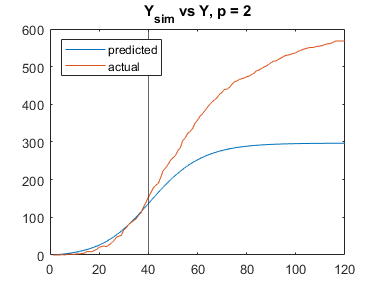

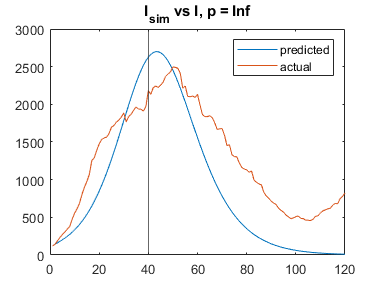

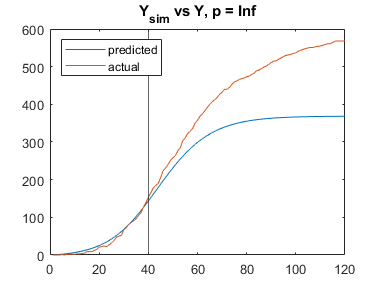

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp(pInd,:);
    [alphaMin, betaMin, gammaMin, deltaMin, NMin] = paramMin{:};
    % Recalculated because it's not stored previously
    [Ssim, Esim, Isim, Rsim] = SEIR_euler(I0, 119, alphaMin, betaMin, deltaMin, NMin);

    % (i) Compare Isim and I
    figure
    plot(Isim)
    hold on
    plot(I_new)
    hold off
    xline(40)
    legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    % (ii) Compare Y and Ysim = gamma * Rsim
    figure
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+119))
    hold off
    xline(40)
    legend(["predicted", "actual"])
    legend('Location','northwest')
    title(['Y_{sim} vs Y, p = ', num2str(p)])
end

### Exercise 2 Part 4

Because for various *p* values, we got minuma for alpha in {0.17}, for R0 in {1.8, 1.9}, for delta in {0.34, 0.40}, and for Nfrac in {0.03}, we would want to search in a range around those values to get more refined parameter estimates. One possible set would be:

alpha in [0.16, 0.18]

R0 in [1.7, 2.0]

delta in [0.33, 0.41]

Nfrac in [0.02, 0.04]

We also would consider much smaller increments for the parameters instead of 0.01 / 0.1.